# **Modeling and Simulation of Trumpet Electro-mechanic Horn**

**2022**

**Vibration and Acoustic Transducers Laboratry**

**Pohang University of Science and Technology**

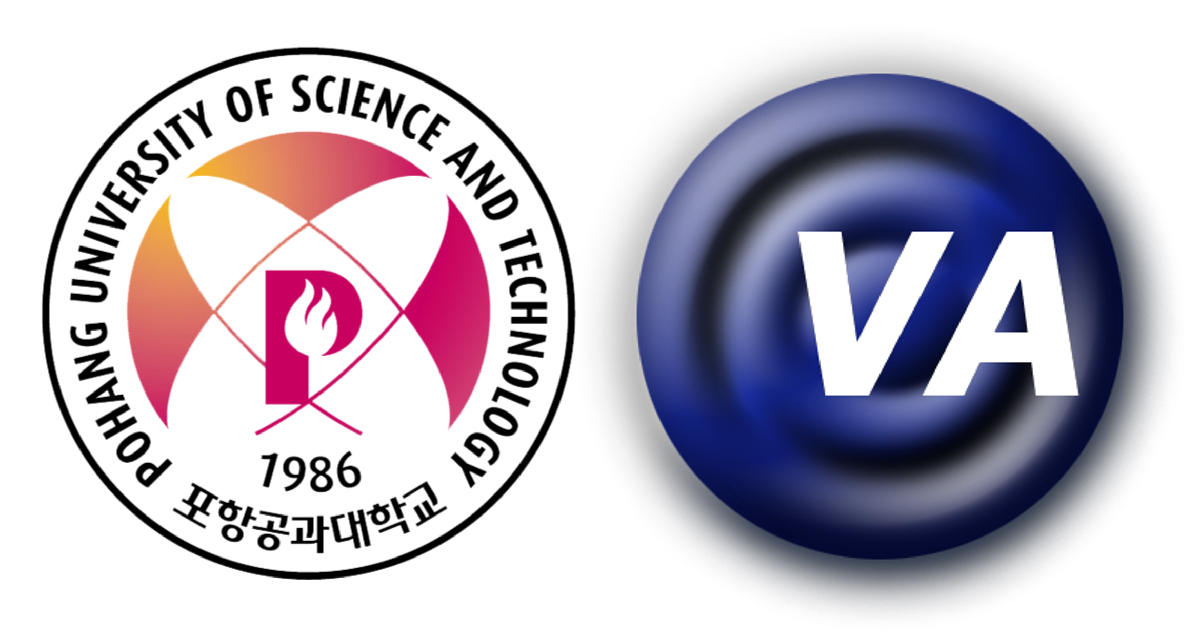

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

## **All(electro-mechano-acoustical) coupled -  time dependent - 3 DOF linear driver model**

Run '../0_overall model/All_Overall_time_dependent_3DOF_linear_driver.slx'.

The following result of FFT is for sound pressure from the pre-simulated 'p_rad_3DOF_1s.mat'.

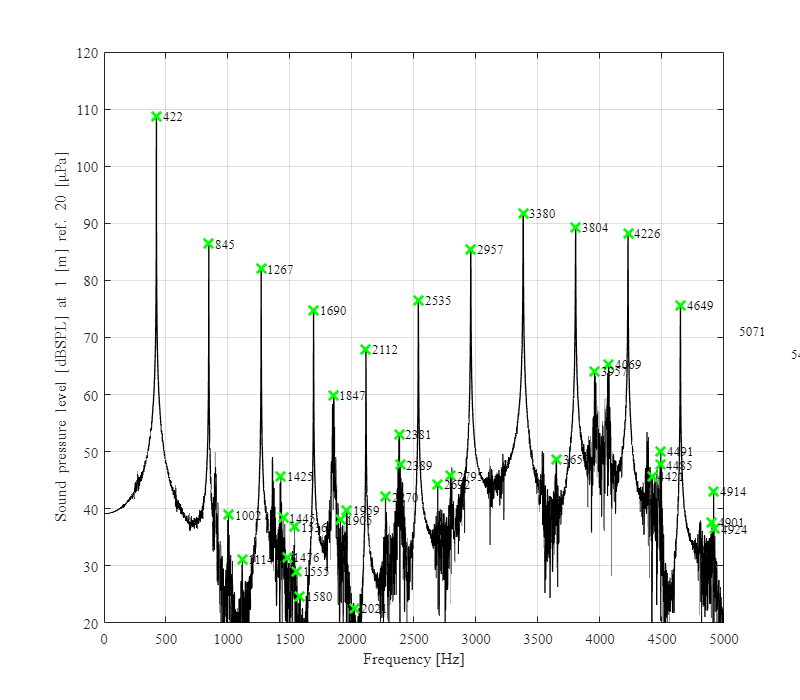

% 실험 결과 비교 추가할 것
ac.all      = load('p_rad_3DOF_1s.mat');
% ac.all      = load('p_rad_3DOF_1s_short.mat');

ac.all.X    = ac.all.p_rad(2,200001:end)';
ac.all.fs   = 1/ac.all.p_rad(1,2);
 
[ac.all.P1, ac.all.f] = execFFT(ac.all.X, ac.all.fs);

plotcompSPLFFT(ac.all.f, 20*log10(abs(ac.all.P1)/air.p_ref));

## **All(electro-mechano-acoustical) coupled -  time dependent - 1 DOF nonlinear driver model**

Run '../0_overall model/All_Overall_time_dependent_1DOF_nonlinear_driver.slx'.

The following result of FFT is for sound pressure from the pre-simulated 'p_rad_nl_1DOF_1s.mat'.

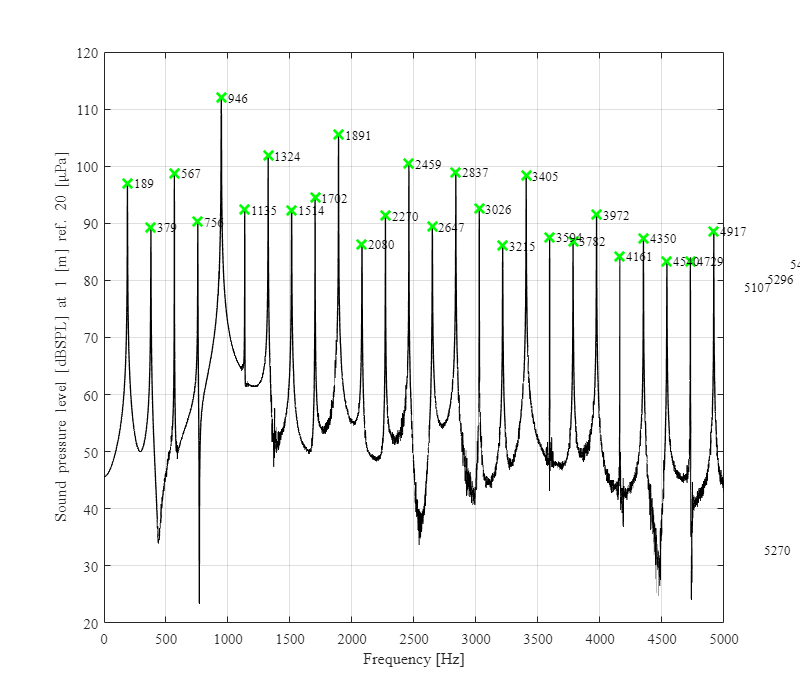

ac.all      = load('p_rad_nl_1DOF_1s.mat');

ac.all.X    = ac.all.p_rad(2,200001:end)';
ac.all.fs   = 1/ac.all.p_rad(1,2);

[ac.all.P1, ac.all.f] = execFFT(ac.all.X, ac.all.fs);

plotcompSPLFFT(ac.all.f, 20*log10(abs(ac.all.P1)/air.p_ref));